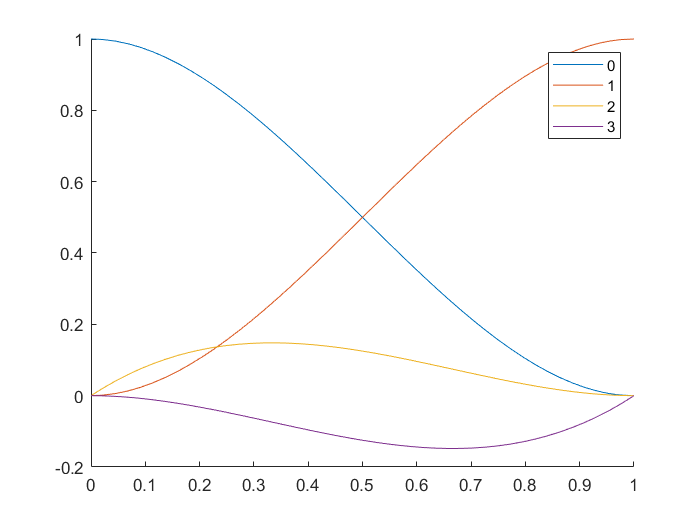

clear; 

syms h u t u0 u1 f0 f1

b0 = getPoly(t, 1, [1,0,0,0]');
b1 = getPoly(t, 1, [0,1,0,0]');
b2 = getPoly(t, 1, [0,0,1,0]');
b3 = getPoly(t, 1, [0,0,0,1]');
figure(1); clf;hold on;
fplot(b0,[0,1])
fplot(b1,[0,1])
fplot(b2,[0,1])
fplot(b3,[0,1])
hold off;
legend('0','1','2','3');

## Integration


weights = sym([0.5,0.5])

$$weights = \left(\begin{array}{cc} \frac{1}{2} & \frac{1}{2} \end{array}\right)$$

tqs = ([-1/sqrt(sym(3)),1/sqrt(sym(3))] + 1)/2

$$tqs = \left(\begin{array}{cc} \frac{1}{2}-\frac{\sqrt{3}}{6} & \frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}\right)$$


u_mid1 = [b0(tqs(1)),b1(tqs(1)),b2(tqs(1))*h,b3(tqs(1))*h] * transpose([u0,u1,f0,f1])

$$u\_mid1 = \begin{array}{l} u_{1}\,\left(3\,\sigma_{2}+2\,\sigma_{1}\right)-u_{0}\,\left(3\,\sigma_{2}+2\,\sigma_{1}-1\right)-f_{1}\,h\,\left(\sigma_{2}+\sigma_{1}\right)-f_{0}\,h\,\left(\frac{\sqrt{3}}{6}+2\,\sigma_{2}+\sigma_{1}-\frac{1}{2}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\sqrt{3}}{6}-\frac{1}{2}\right)}^{3}\\ \sigma_{2}={\left(\frac{\sqrt{3}}{6}-\frac{1}{2}\right)}^{2} \end{array}$$

u_mid2 = [b0(tqs(2)),b1(tqs(2)),b2(tqs(2))*h,b3(tqs(2))*h] * transpose([u0,u1,f0,f1])

$$u\_mid2 = \begin{array}{l} u_{0}\,\left(2\,\sigma_{1}-3\,\sigma_{2}+1\right)+u_{1}\,\left(3\,\sigma_{2}-2\,\sigma_{1}\right)+f_{0}\,h\,\left(\frac{\sqrt{3}}{6}-2\,\sigma_{2}+\sigma_{1}+\frac{1}{2}\right)-f_{1}\,h\,\left(\sigma_{2}-\sigma_{1}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\sqrt{3}}{6}+\frac{1}{2}\right)}^{3}\\ \sigma_{2}={\left(\frac{\sqrt{3}}{6}+\frac{1}{2}\right)}^{2} \end{array}$$

syms f_mid1 f_mid2;
incre = weights * [f_mid1; f_mid2] * h;

[b0(tqs(1)),b1(tqs(1)),b2(tqs(1))*h,b3(tqs(1))*h]

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 1-2\,\sigma_{1}-3\,\sigma_{2} & 3\,\sigma_{2}+2\,\sigma_{1} & -h\,\left(\frac{\sqrt{3}}{6}+2\,\sigma_{2}+\sigma_{1}-\frac{1}{2}\right) & -h\,\left(\sigma_{2}+\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\sqrt{3}}{6}-\frac{1}{2}\right)}^{3}\\ \sigma_{2}={\left(\frac{\sqrt{3}}{6}-\frac{1}{2}\right)}^{2} \end{array}$$

[b0(tqs(2)),b1(tqs(2)),b2(tqs(2))*h,b3(tqs(2))*h]

$$ans = \begin{array}{l} \left(\begin{array}{cccc} 2\,\sigma_{1}-3\,\sigma_{2}+1 & 3\,\sigma_{2}-2\,\sigma_{1} & h\,\left(\frac{\sqrt{3}}{6}-2\,\sigma_{2}+\sigma_{1}+\frac{1}{2}\right) & -h\,\left(\sigma_{2}-\sigma_{1}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\sqrt{3}}{6}+\frac{1}{2}\right)}^{3}\\ \sigma_{2}={\left(\frac{\sqrt{3}}{6}+\frac{1}{2}\right)}^{2} \end{array}$$

## Stability

syms lambda kappa
u_mid1_lam = subs(u_mid1, [f0,f1],[u0,u1] * lambda);
u_mid2_lam = subs(u_mid2, [f0,f1],[u0,u1] * lambda);

incre_lam = collect(subs(expand(incre), [f_mid1,f_mid2], [u_mid1_lam, u_mid2_lam] * lambda), [u0,u1])

$$incre\_lam = \begin{array}{l} \left(-\frac{h\,\lambda \,\left(3\,{\sigma_{1}}^{2}+2\,{\sigma_{1}}^{3}+h\,\lambda \,\left(\frac{\sqrt{3}}{6}+2\,{\sigma_{1}}^{2}+{\sigma_{1}}^{3}-\frac{1}{2}\right)-1\right)}{2}+\frac{h\,\lambda \,\left(2\,{\sigma_{2}}^{3}-3\,{\sigma_{2}}^{2}+h\,\lambda \,\left(\frac{\sqrt{3}}{6}-2\,{\sigma_{2}}^{2}+{\sigma_{2}}^{3}+\frac{1}{2}\right)+1\right)}{2}\right)\,u_{0}+\left(-\frac{h\,\lambda \,\left(2\,{\sigma_{2}}^{3}-3\,{\sigma_{2}}^{2}+h\,\lambda \,\left({\sigma_{2}}^{2}-{\sigma_{2}}^{3}\right)\right)}{2}+\frac{h\,\lambda \,\left(3\,{\sigma_{1}}^{2}+2\,{\sigma_{1}}^{3}-h\,\lambda \,\left({\sigma_{1}}^{2}+{\sigma_{1}}^{3}\right)\right)}{2}\right)\,u_{1}\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}}{6}-\frac{1}{2}\\ \sigma_{2}=\frac{\sqrt{3}}{6}+\frac{1}{2} \end{array}$$

K = subs(simplify(solve(incre_lam + (u0 - u1), u1 )/u0), h*lambda, kappa)

$$K = \frac{\kappa^{2}+6\,\kappa +12}{\kappa^{2}-6\,\kappa +12}$$

## Stability Reigon

test_range = 500;
rSamp = linspace(-test_range,test_range,201);
iSamp = linspace(-test_range,test_range,201);
[rSampM,iSampM] = meshgrid(rSamp,iSamp);
zSampM = rSampM + 1i * iSampM;
Kf = matlabFunction(symfun(K, [kappa]));

% alphatest = 2/3;
KM = abs(Kf(zSampM));

s = surf(rSampM,iSampM, min(KM,1), 'LineStyle',"none")

s =   Surface - 属性:

       EdgeColor: [0 0 0]
       LineStyle: 'none'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [201×201 double]
           YData: [201×201 double]
           ZData: [201×201 double]
           CData: [201×201 double]

  显示 所有属性


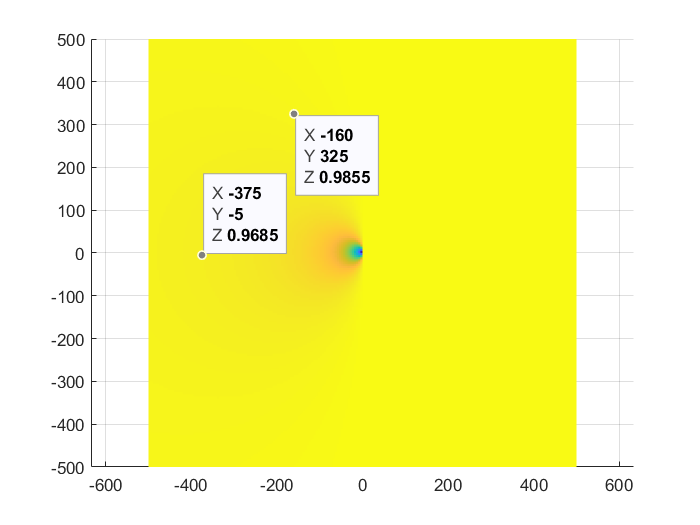

view(0,90)
axis equal;

function po = getPoly(t, h, cond)
    bases(t) = [1,t,t^2,t^3];
    dB(t) = diff(bases,t);
    valBases = [bases(0); bases(h);...
        dB(0); dB(h)];
    coefs = valBases \ cond;
    po = bases * coefs;
end

